# **Binary classification using a RNN & CNN - EEG data**

clc; clear; close all;

## **Load Data**

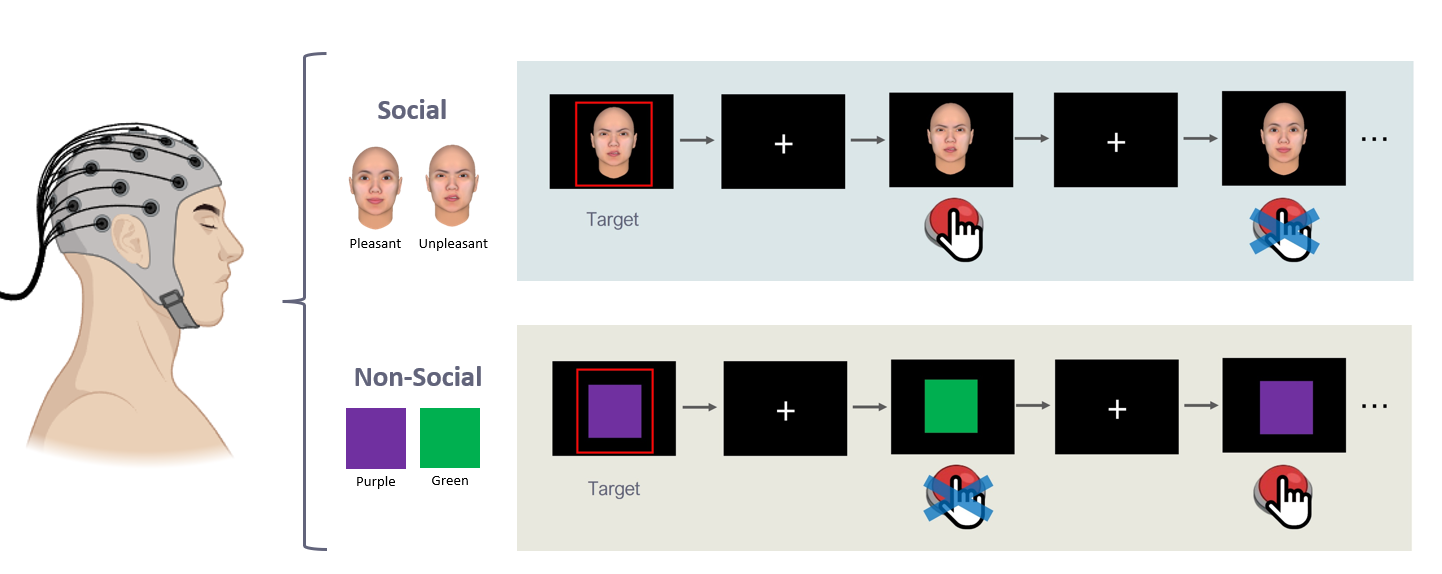

data = importdata('data_eeg.mat')

data = 다음 필드를 포함한 1×10 struct 배열:
    eeg
    IsPatients
    eventlabel
    eventstamp
    fs


% get EEG data
eeg = {data.eeg};
nsubject = length( eeg )

nsubject = 10

% get label information
patient_label = categorical( [data.IsPatients] );
unique( patient_label ) % 2-class

ans = 1×2 categorical 배열
     false      true 


event_label = { data.eventlabel };

### EEG Event and Time Window Selection

#### Time window seleciton

fs = data(1).fs;
time_window = [-0.2 1.0]; % pre-determined epoching window. 
time = [-0.2 : 1/fs : 1.0]; time(1) = [];
timeidx = time> 0.1 & time <= 0.6; % We will use the time range of 100ms to 600ms after the onset trigger.

#### Event selection

% S  10 = Social/Go (SG) - V
% S  11 = Social/NoGo (SN)
% S  20 = Nonsocial/Go (NG)
% S  21 = Nonsocial/NoGo (NN)
go_eeg = [];
for isubj = 1: nsubject
    go_trial_idx = strcmp( event_label{ isubj }, 'S  10' );
    go_eeg(:, :, :, isubj) = eeg{ isubj }( :, timeidx, go_trial_idx );
end

[nch, L, ntrial, ~] = size( go_eeg )

nch = 31

L = 250

ntrial = 30

nsamples = ntrial*nsubject

nsamples = 300

feat = reshape( go_eeg, nch, L, nsamples ); % inter-subject training.

label = repmat( patient_label, ntrial, 1); 
label = label(:);

## **Binary classification using a Bidirectional RNN**

% Get the preferred format of input features for using an RNN
feat_lstm = squeeze( mat2cell( feat, nch, L, ones(nsamples,1)) )

feat_lstm = 300×1 cell 배열
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}
    {31×250 double}


length(feat_lstm)

ans = 300

#### **Partitioning the training and test data**

rng(1); % fixed random seed.
cv = cvpartition( label, 'KFold', 10 );
test_idx = test( cv, 1 ); % Randomly select 10% of the total number of samples for testing
train_idx = training( cv, 1);

train_feat = feat_lstm( train_idx );
train_lb = label( train_idx );
length(train_feat)

ans = 270

test_feat = feat_lstm( test_idx );
test_lb = label( test_idx );
length(test_feat)

ans = 30

## **Learning a bi-LSTM model**

% set hyperparameter
nfeatures = nch;
numHiddenUnits = 10;
numClasses = 2; % ADHD vs. healthy

% define bi-LSTM layer
layers = [
    sequenceInputLayer( nfeatures, Normalization="zscore" ) 
    bilstmLayer( numHiddenUnits, 'OutputMode', 'last' ) %-%
    fullyConnectedLayer( numClasses )
    softmaxLayer
    classificationLayer]

layers =   다음 계층을 포함한 5×1 Layer 배열:

     1   ''   시퀀스 입력   시퀀스 입력 (차원 31개)
     2   ''   BiLSTM      BiLSTM (은닉 유닛 10개)
     3   ''   완전 연결     2 완전 연결 계층
     4   ''   소프트맥스    소프트맥스
     5   ''   분류 출력     crossentropyex

% set learning parameter
max_epochs = 40;
mini_batch_size = 32;

options = trainingOptions('adam', ...
    'ExecutionEnvironment', 'cpu',...
    'MaxEpochs', max_epochs, ...
    'MiniBatchSize', mini_batch_size, ...
    'ValidationData', {test_feat, test_lb}, ...
    'ValidationFrequency', 5, ...
    'Shuffle', 'never', ...
    'Verbose',false, ...
    'Plots','training-progress');

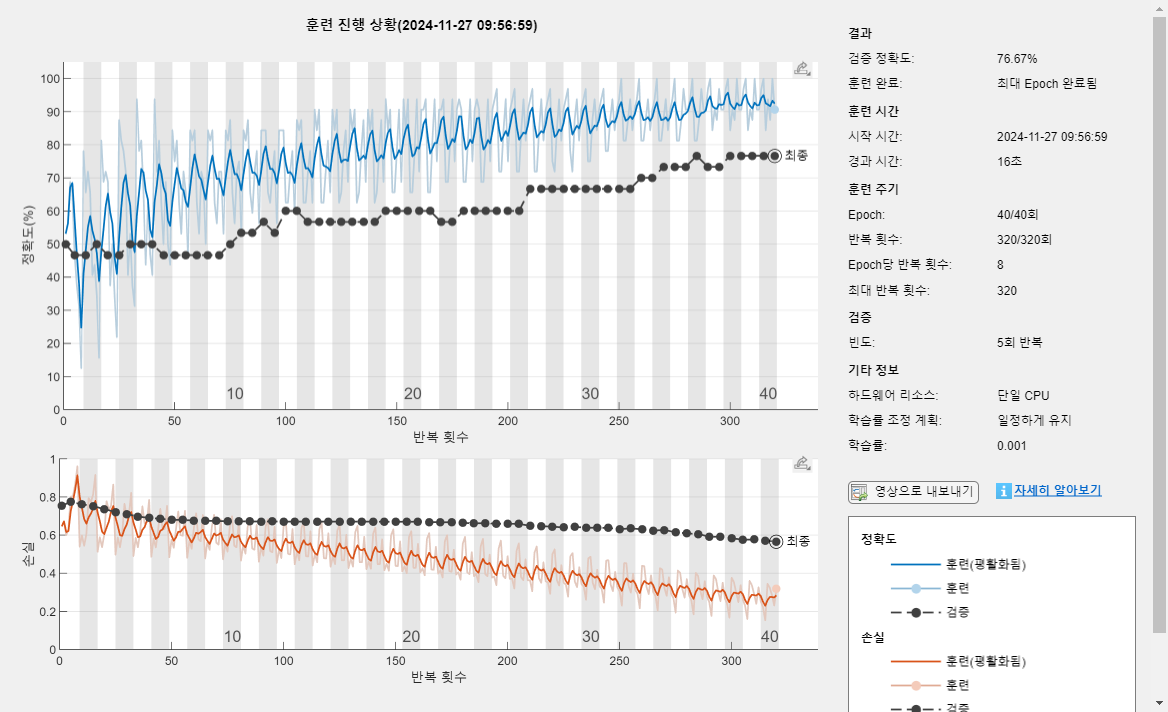

% Train LSTM
net_lstm = trainNetwork( train_feat, train_lb, layers, options);

% Prediction
pred = classify( net_lstm, test_feat);

acc_lstm = mean( pred == test_lb );
fprintf('| LSTM Accuracy = %0.2f %% | \n', acc_lstm.*100);

| LSTM Accuracy = 76.67 % | 


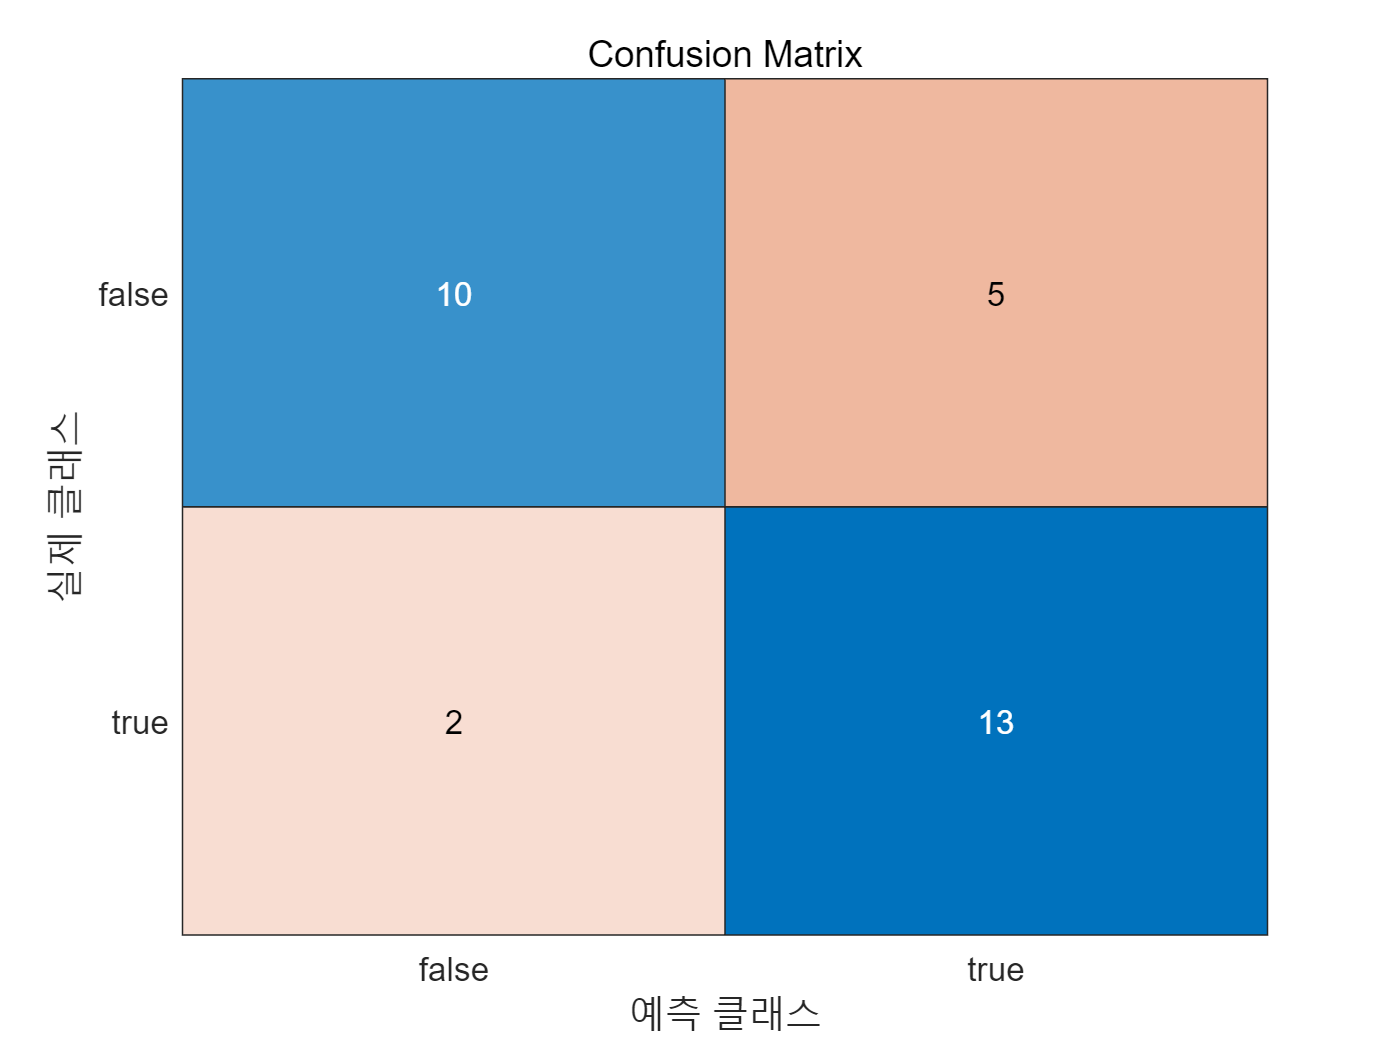

figure;
confusionchart( test_lb, pred )    % Confusion matrix
title('Confusion Matrix');

## Analyze the components inside the learned LSTM

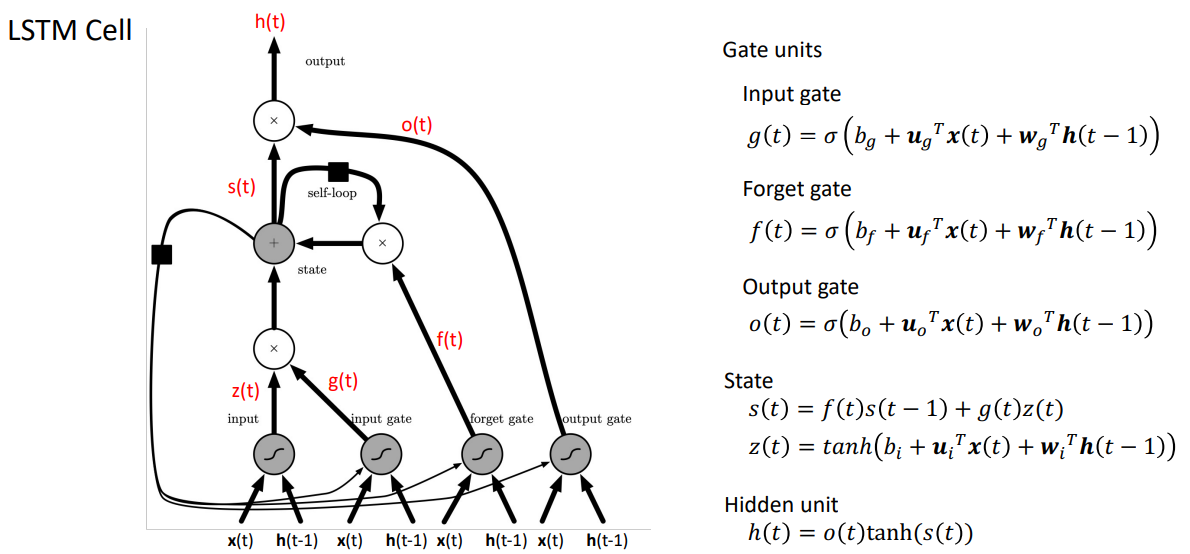

% Forget gate output
sequenceLength = L;
bilstm = net_lstm.Layers(2);

h = bilstm.HiddenState; % hidden state
s = bilstm.CellState;   % cell state

% Extracting weights and biases
U = bilstm.InputWeights;
W = bilstm.RecurrentWeights;
b = bilstm.Bias;

% Determine forward parameter indices
idxForward = 1:4*numHiddenUnits;
% Forward states
h_fwd = h(1:numHiddenUnits);
s_fwd = s(1:numHiddenUnits);
% Forward parameters
U_fwd = U(idxForward,:);
W_fwd = W(idxForward,:);
b_fwd = b(idxForward);

% Backward states ---------------------------------------
% idxBackward = 4*numHiddenUnits+1:8*numHiddenUnits;

% h_bwd = h(numHiddenUnits+1:end);
% s_bwd = s(numHiddenUnits+1:end);

% U_bwd = U(idxBackward,:);
% W_bwd = W(idxBackward,:);
% b_bwd = b(idxBackward);

% Indices for the each gate components
input_idx = 1:4:(4*numHiddenUnits);
forget_idx = 2:4:(4*numHiddenUnits);
cand_idx = 3:4:(4*numHiddenUnits);
output_idx = 4:4:(4*numHiddenUnits);

% Extracting the relevant weights and biases for the forget gate
u_f = U_fwd(forget_idx, :);
w_f = W_fwd(forget_idx, :);
b_f = b_fwd(forget_idx);

% Extracting the relevant weights and biases for the input gate
u_g = U_fwd(input_idx, :);
w_g = W_fwd(input_idx, :);
b_g = b_fwd(input_idx);

% Extracting the relevant weights and biases for the ouput gate
u_o = U_fwd(output_idx, :);
w_o = W_fwd(output_idx, :);
b_o = b_fwd(output_idx);

% Extracting the relevant weights and biases for the cell candidate
u_i = U_fwd(cand_idx, :);
w_i = W_fwd(cand_idx, :);
b_i = b_fwd(cand_idx);

% get example sample for each class
clear X
idx = find( test_lb == 'false' );
idx = idx(1);
X(1) = test_feat(idx);

idx = find( test_lb == 'true');
idx = idx(1);
X(2) = test_feat(idx);

clear output_f input_f
sigma_t = @(t) 1 ./ (1 + exp(-t)); 
for iclass = 1:2
    for t = 1:sequenceLength
        
        x_t = X{iclass}(:, t); % Current input
        


#### `!!!Fill the blank!!!`

        % LSTM forward pass calculations for the forget gate
        forget_gate = sigma_t( b_f + u_f * x_t + w_f * h_fwd );
    
        % input_gate
        input_gate = sigma_t( b_g + u_g * x_t + w_g * h_fwd );
    
        % output_gate
        output_gate = sigma_t( b_o + u_o * x_t + w_o * h_fwd );
    
        % cell_candidates
        cell_candidates = tanh( b_i +  u_i * x_t + w_i * h_fwd ); % hyperbolic tangent
    
        % update the cell state 's(t)' and hidden state 'h(t)' 
        s_fwd = forget_gate .* s_fwd + input_gate .* cell_candidates; 
        h_fwd = output_gate .* tanh(s_fwd); 
    
        % tracking the forget gate's output
        output_f{iclass}(:, t) = forget_gate;
        input_f{iclass}(:, t) = input_gate .* cell_candidates;
    end
end

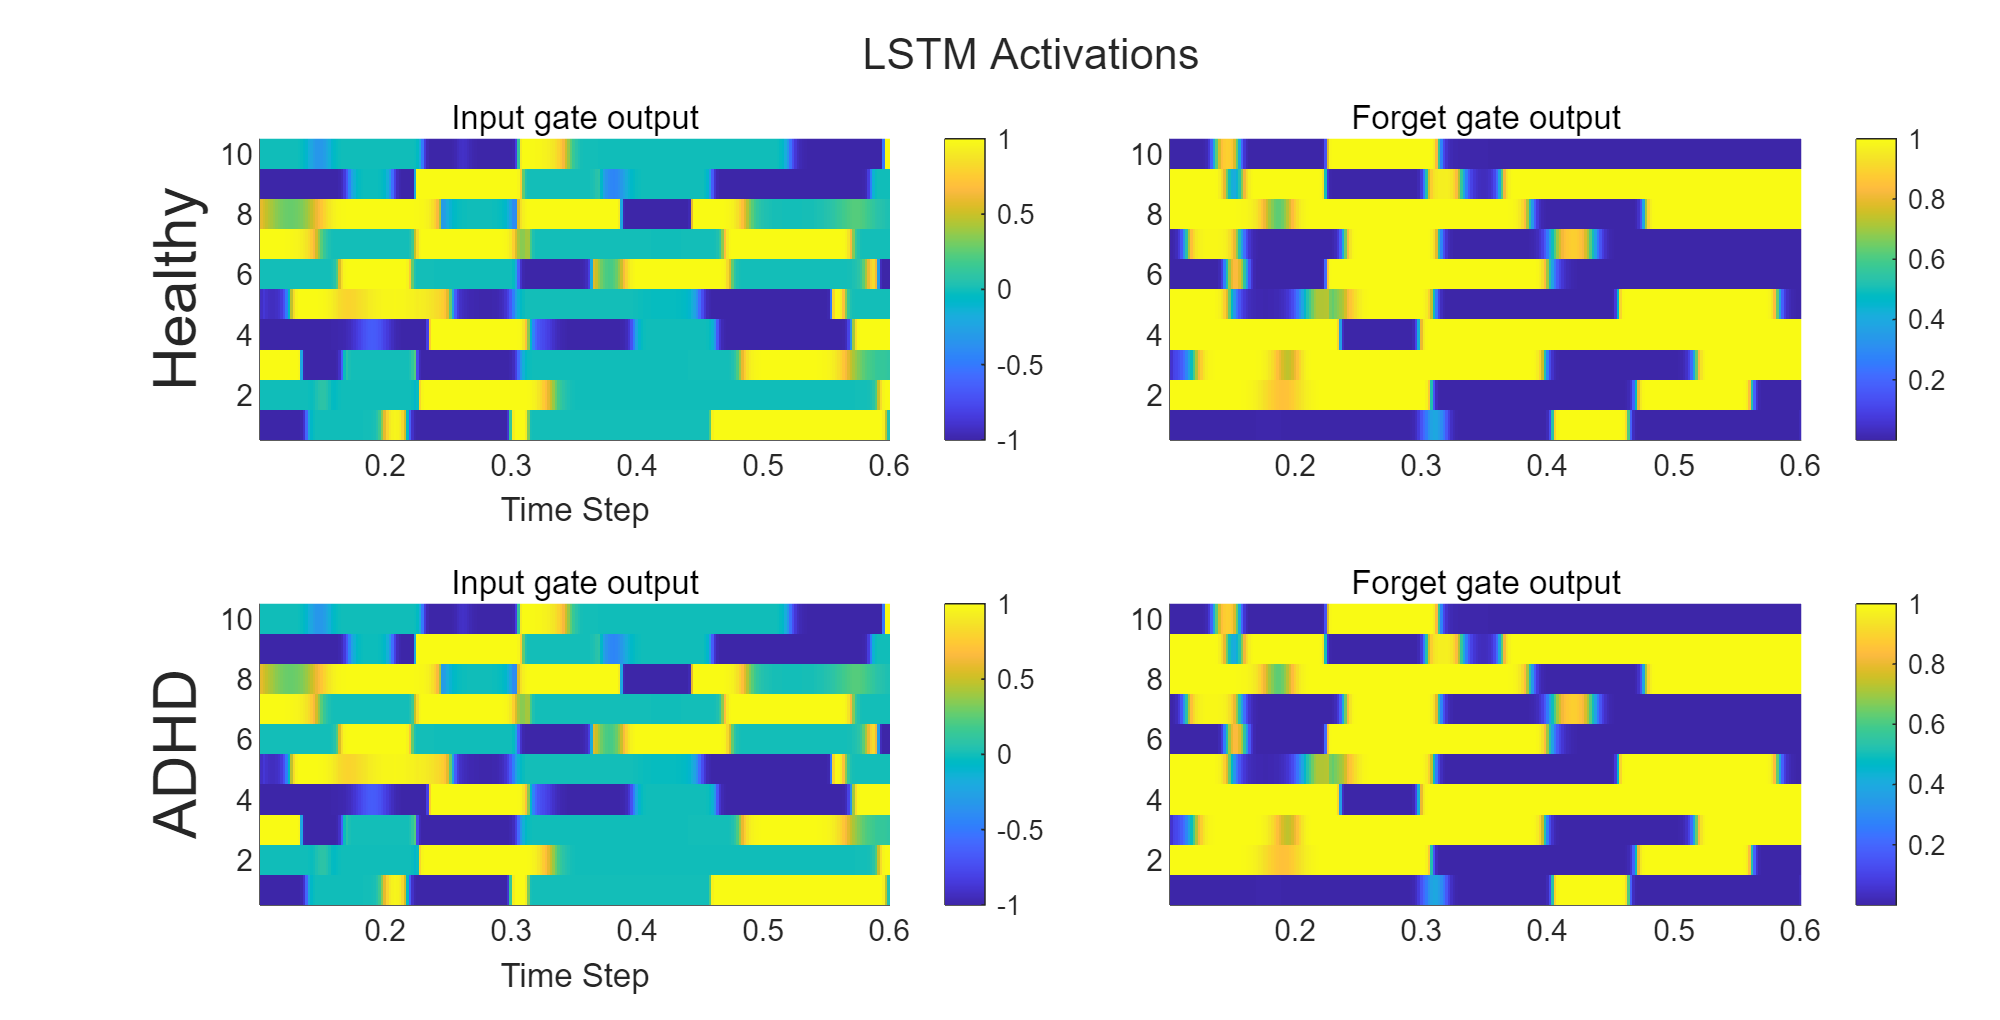

figure('Position',[300 450 1020 520]);
tiledlayout(2,2);
for iclass = 1:2
    nt(iclass,1) = nexttile();

    imagesc('XData', time(timeidx), 'YData', [1:numHiddenUnits],'CData', input_f{isubj});
    xlim('tight'); ylim('tight');
    title("Input gate output");
    xlabel("Time Step");
    colorbar;

ans =     31   250     1   300


    
    nt(iclass,2) = nexttile();
    imagesc('XData', time(timeidx), 'YData', [1:numHiddenUnits],'CData', output_f{isubj});
    xlim('tight'); ylim('tight');
    title("Forget gate output");
    colorbar;
    
    sgtitle("LSTM Activations")
end


ans = 270

% set label options
ax = nt(1,1);
set(get( ax, 'YLabel'),'String','Healthy', 'FontSize',18);

ans = 30

ax = nt(2,1);
set(get( ax, 'YLabel'),'String','ADHD', 'FontSize',18);

## **Binary classification using a CNN**

% Get the preferred format of input features for using an CNN
feat_cnn = permute( feat, [1,2,4,3]);
size(feat_cnn)
rng(1); % fixed random seed.

% Randomly select 10% of the total number of samples for testing
cv = cvpartition( label, 'KFold', 10 );
test_idx = test( cv, 1 ); 
train_idx = training( cv, 1);

train_feat = feat_cnn(:, :, :, train_idx);
train_lb = label( train_idx );
size(train_feat, 4)
test_feat = feat_cnn(:, :, :, test_idx);
test_lb = label(test_idx);
size(test_feat, 4)

## **Training a CNN model**

#### `!!!Fill the blank!!!`

% set hyperparameters 

layers =   다음 계층을 포함한 12×1 Layer 배열:

     1   ''   영상 입력          31×250×1 영상 (정규화: 'zerocenter')
     2   ''   2차원 컨벌루션      32개 3×3 컨벌루션(스트라이드: [1  1], 채우기: 'same')
     3   ''   배치 정규화        배치 정규화
     4   ''   ReLU             ReLU
     5   ''   2차원 최댓값 풀링   2×2 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   ''   2차원 컨벌루션      64개 3×3 컨벌루션(스트라이드: [1  1], 채우기: 'same')
     7   ''   배치 정규화        배치 정규화
     8   ''   ReLU             ReLU
     9   ''   2차원 최댓값 풀링   2×2 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   ''   완전 연결          2 완전 연결 계층
    11   ''   소프트맥스         소프트맥스
    12   ''   분류 출력          crossentropyex

% Hint : check the size of feat_cnn. 
inputSize = [nch L 1]; % size of input data(image): height * width * channels
numClasses = 2; % number of class

#### `!!!Fill the blank!!!`

Write a name of layers **in the correct order** to stack the following four layers for a CNN architecture. 

Just replace "`???"` with the layers listed below:

- `convolution2dLayer`

- `batchNormalizationLayer`

- `reluLayer`

- `maxPooling2dLayer`

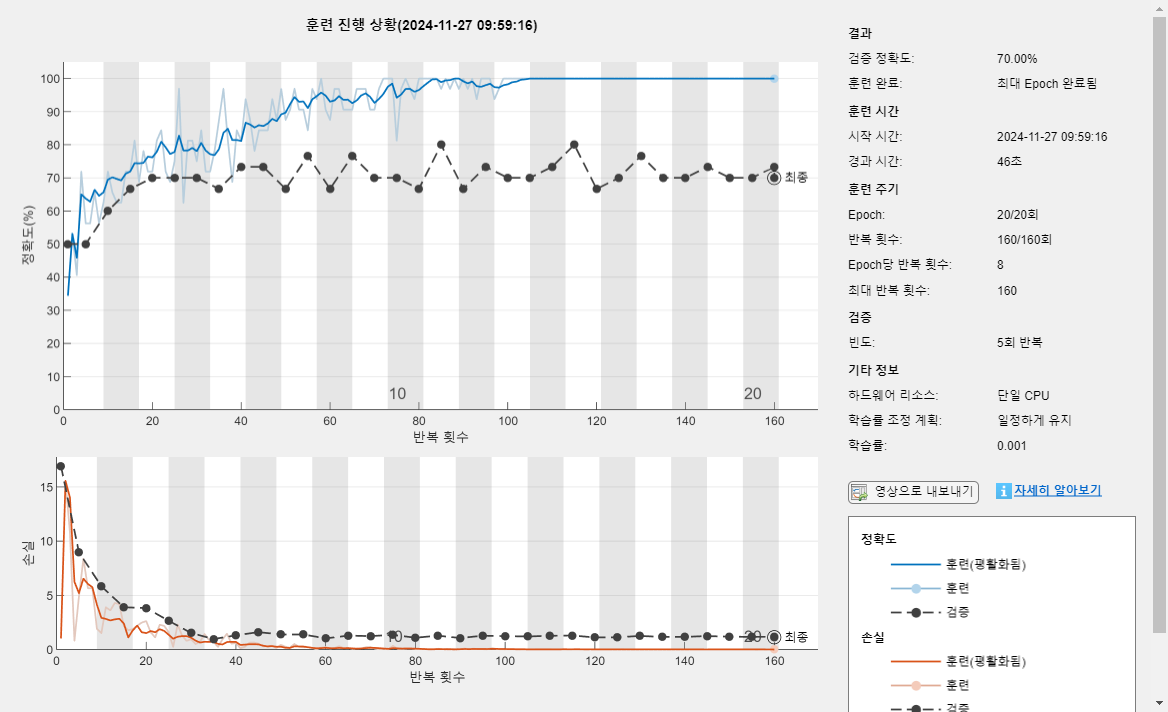

layers = [
    % input layer    
    imageInputLayer( inputSize )  

    % convolution layer1
    convolution2dLayer(3, 32, 'Padding', 'same') 
    batchNormalizationLayer
    reluLayer 
    maxPooling2dLayer(2,'Stride',2) % 2 x 2 pool size, stride 2 (without overlap)

    % convolution layer2
    convolution2dLayer(3, 64, 'Padding', 'same') 

    batchNormalizationLayer
    reluLayer 
    maxPooling2dLayer(2,'Stride',2) % 2 x 2 pool size, stride 2 (without overlap)



| CNN Accuracy = 70.00 % | LSTM Accuracy = 76.67 % 


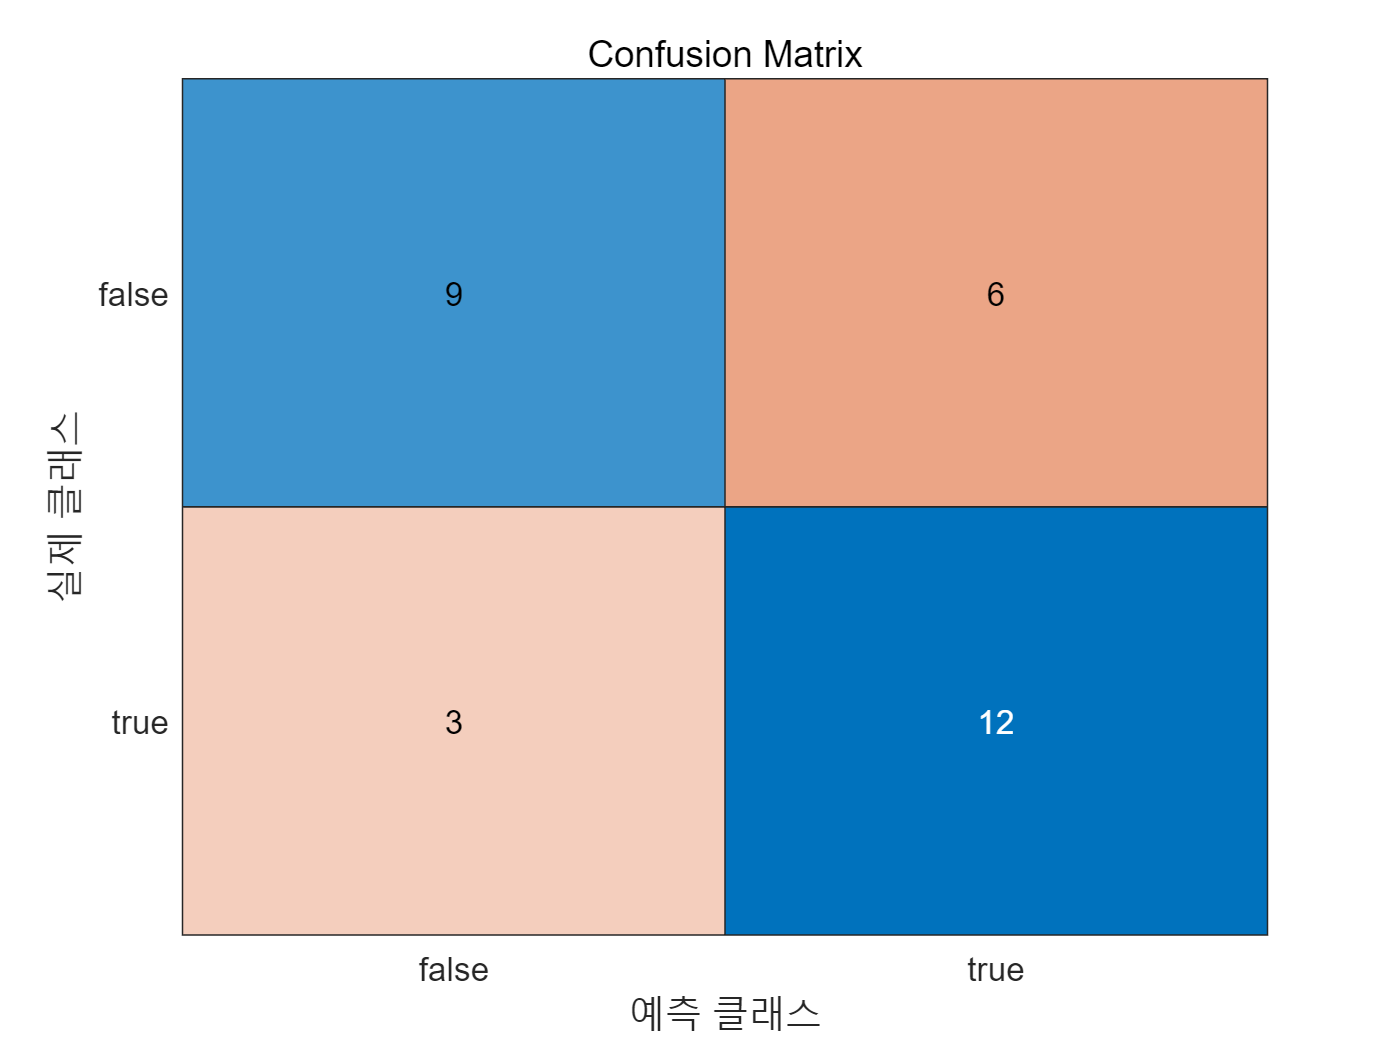

    % output layer
    % classification using softmax function
    fullyConnectedLayer(numClasses)

    softmaxLayer
    classificationLayer
    ]

max_epochs = 20;
mini_batch_size = 32;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu',...
    'MaxEpochs', max_epochs, ...
    'MiniBatchSize', mini_batch_size, ...
    'ValidationData', {test_feat, test_lb}, ...
    'ValidationFrequency', 5, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots','training-progress');

% Train CNN
net_cnn = trainNetwork(train_feat, train_lb, layers, options);

% Prediction
pred = classify( net_cnn, test_feat);
acc_cnn = mean( pred == test_lb );
fprintf('| CNN Accuracy = %0.2f %% | LSTM Accuracy = %0.2f %% \n', acc_cnn*100, acc_lstm*100);
figure;
confusionchart( test_lb, pred )    % Confusion matrix
title('Confusion Matrix');

## Analyze the components inside the learned CNN

% Extract the weight and bias from first layer
conv1_W = net_cnn.Layers(2).Weights;
conv1_b = net_cnn.Layers(2).Bias;

% Extract the weight and bias from second layer
conv2_W = net_cnn.Layers(6).Weights;
conv2_b = net_cnn.Layers(6).Bias;

% get example sample for each class
h_idx = find(test_lb == 'false');
h_idx = h_idx(1);
adhd_idx = find(test_lb == 'true');
adhd_idx = adhd_idx(1);

X = {};
X{1} = test_feat(:, :, :, h_idx );
X{2} = test_feat(:, :, :, adhd_idx );

sampled_in = 10;
sampled_out = 30;
k = 2; s = 2; % pooling kernel size and stride

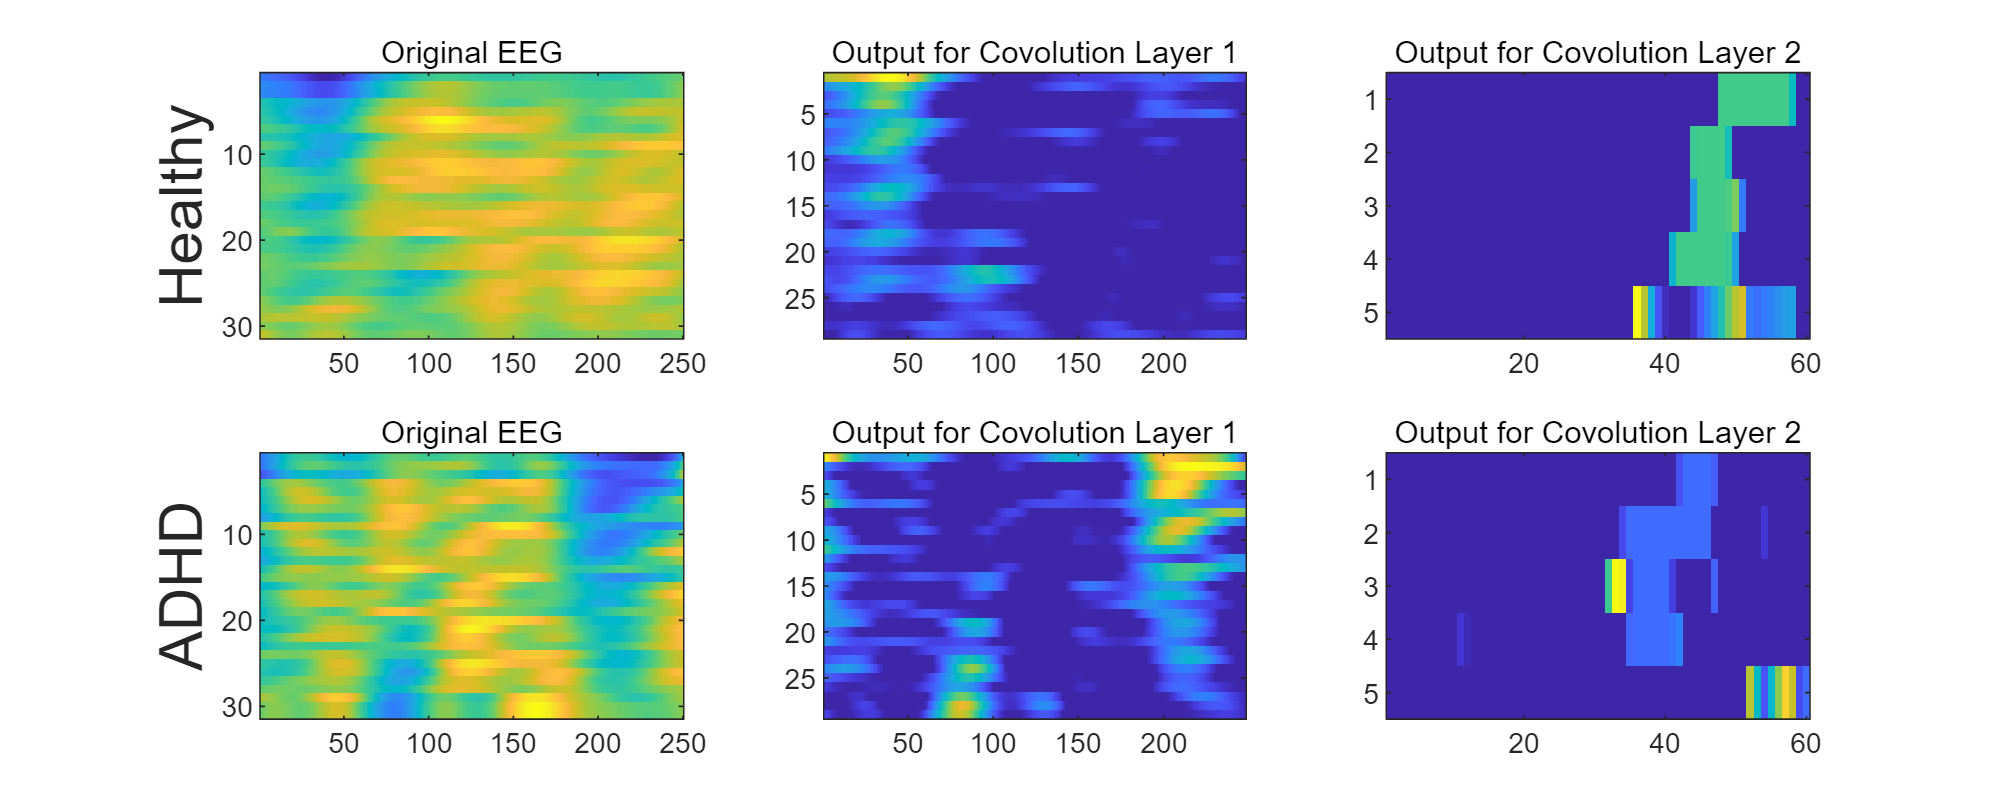

output1 = {};

output2 = {};
for idx = 1: 2
    x = X{idx};

    % -----------------------------------------------------------------------
    % Convolution 1
    conv_output1 = [];
    conv_output1 = conv2(x, conv1_W(:, :, :, sampled_in ),'valid');
    conv_output1 = conv_output1 + conv1_b(:, :, sampled_in );
        
    % Relu for first filter
    output1{idx} = conv_output1(:,:) .* double( conv_output1(:,:) > 0 );

    % max pooling
    [rows, cols] = size(output1{idx});
    outputRows = floor((rows - k) / s) + 1;
    outputCols = floor((cols - k) / s) + 1;
    pool1 = [];
    for i = 1: s : outputRows
        for j = 1: s : outputCols
            % Extract the current block
            block = output1{idx}(i:(i+k-1), j:(j+k-1));
            pool1(ceil(i/s), ceil(j/s)) = max( block(:) );
        end
    end
    x = pool1;

    % -----------------------------------------------------------------------
    % Convolution 2
    conv_output2 = [];
    conv_output2 = conv2(x, conv2_W(:, :, sampled_in, sampled_out ),'valid');
    conv_output2 = conv_output2 + conv2_b(:, :, sampled_out );
    % Relu for second filter
    output2{idx} = conv_output2 .* double( conv_output2 > 0 );
end    
    

plotting

figure('Position',[400 290 1040 420]);
tl = tiledlayout(2,3);
for i = 1:2
    nt(i,1) = nexttile();
    imagesc(X{i});
    title('Original EEG');

    nt(i,2) = nexttile();
    imagesc(output1{i});
    title('Output for Covolution Layer 1');

    nt(i,3) = nexttile();
    imagesc(output2{i});
    title('Output for Covolution Layer 2');
end

% set label options
ax = nt(1,1);
set(get( ax, 'YLabel'),'String','Healthy', 'FontSize',18);
ax = nt(2,1);
set(get( ax, 'YLabel'),'String','ADHD', 'FontSize',18);